s = tf('s');

S_R = 40;
q_p = 30;
h3 = 18.5;
g = 981;
SL30 = 2*q_p/sqrt(2*g*h3);


A = -(SL30/S_R)*sqrt(g/(2*h3))

A = -0.0405

B = 1/S_R

B = 0.0250

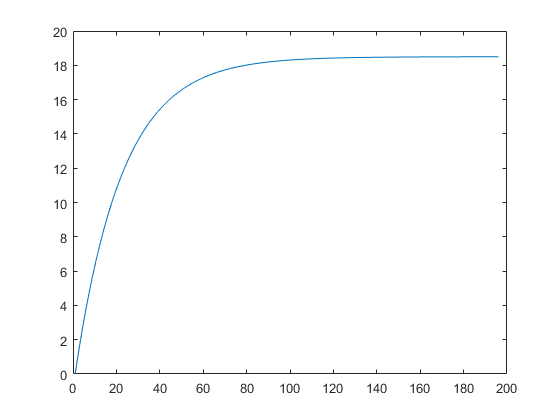

C = 0;

% Open-loop control system
Gp = B/(s-A);
y = step(Gp)*q_p;
plot(y);

% attention time
save(y,open-loop-sim.txt);

Error using open (line 46)
Not enough input arguments.


% Closed-loop control system
Kp = 10;
T = (Kp*Gp)/(1 + Kp*Gp);
y = step(Gp)*h3;
plot(y);